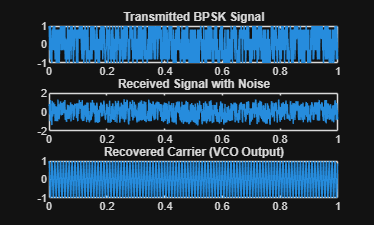

clc;
clear;
close all;

%% Parameters
fs = 1000;          % Sampling frequency
fc = 100;           % Carrier frequency
N = 1000;           % Number of samples
t = (0:N-1)/fs;

%% Generate BPSK Signal
data = randi([0 1],1,N);
bpsk = 2*data - 1;               % Convert to +1 / -1

carrier = cos(2*pi*fc*t);
tx = bpsk .* carrier;            % BPSK modulated signal

%% Channel Noise
rx = tx + 0.2*randn(1,N);

%% Costas Loop Initialization
vco_phase = 0;
vco_freq = fc;
loop_gain = 0.01;

vco_out = zeros(1,N);
error = zeros(1,N);

for i = 1:N
    
    % VCO signal
    vco_out(i) = cos(2*pi*vco_freq*t(i) + vco_phase);
    
    % Mixers (I and Q)
    I = rx(i) * vco_out(i);
    Q = rx(i) * sin(2*pi*vco_freq*t(i) + vco_phase);
    
    % Error signal
    error(i) = I * Q;
    
    % Loop filter / phase update
    vco_phase = vco_phase + loop_gain * error(i);
    
end

%% Plot Results
figure
subplot(3,1,1)
plot(t,tx)
title('Transmitted BPSK Signal')

subplot(3,1,2)
plot(t,rx)
title('Received Signal with Noise')

subplot(3,1,3)
plot(t,vco_out)
title('Recovered Carrier (VCO Output)')